# Homework 4: Morphology Segmentation

#### Name: Grant Roberts

#### Due: 04/09/2020

#### BMI/CS 567: Medical Image Analysis 

## **4.1     Segmentation**

**Use any combination of the segmentation techniques we have studied in class (region growing, erosion, dilation, thresholding, etc.) to segment the metastatic tumor highlighted in the following brain MRI:**

                                                                               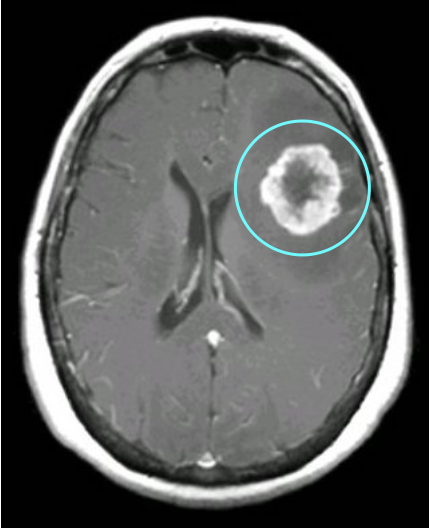

**You can find this MRI (metastatic.jpg) on the course website. Aside from the techniques we have studied in class, you may also use any other technique you want (e.g., something you find on a book, research papers, the internet, or something you come up with), but you must explain such technique clearly, where you got it from, and why you chose to use it. Hand in your code and your segmentation.**

brain = imread('metastatic.jpg');
brain = double(rgb2gray(brain));

seedPoint = [161,236]; % Initial seedpoint (selected near bottom edge of tumor)
threshold = 8; % Region growing criteria
segmented = regionGrow(brain,seedPoint,threshold); % Region grow in tumor
segmented = dilation(segmented); % Dilate to connect inside

## **4.2     Evaluation**

**On the course website you can also find the file ground_truth.png, which contains the hand-segmented tumor:**

                                                                            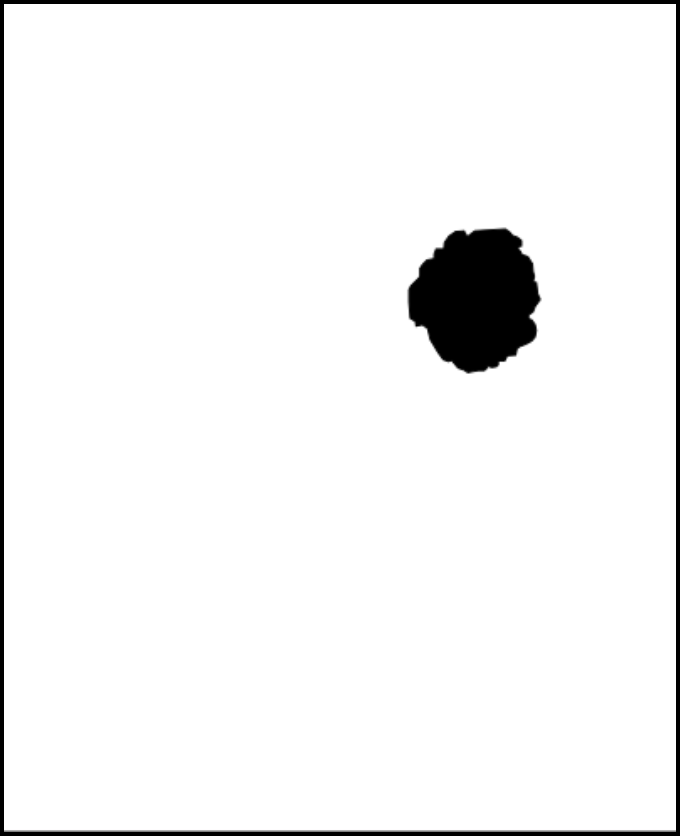

**(a) Compute the Hausdorff distance between your segmentation and the ground truth.**

truth = imread('ground_truth.png');
truth = rgb2gray(truth)<255; % Binarize and inverse image
truth = imresize(truth,size(brain)); % Make segmented and ground truth images same size
segmented = imbinarize(segmented); % Binarize segmented image

%Create indices of boundary points
contourSegmented = cell2mat(bwboundaries(segmented)); %Border points in segmented (Nx2)
contourTruth = cell2mat(bwboundaries(truth)); %Get all border points in segmented (Mx2)

% Calculate Hausdorff
for i=1:length(contourSegmented)
    for j=1:length(contourTruth)
        % Find euclidean distance between points
        distances1(i,j) = norm(contourSegmented(i,:)-contourTruth(j,:)); 
    end 
end
firstTerm = max(min(distances1,[],2)); % Get maximum of all mins

for i=1:length(contourTruth)
    for j=1:length(contourSegmented)
        distances2(i,j) = norm(contourTruth(i,:)-contourSegmented(j,:));
    end 
end
secondTerm = max(min(distances2,[],2)); % Get maximum of all mins

hausdorff = max(firstTerm,secondTerm); % Find max of either term
disp(['Hausdorff Distance = ' num2str(hausdorff)]);

Hausdorff Distance = 3.6056


**(b) Compute the Dice coefficient between your segmentation and the ground truth.**

% Compute dice coefficient
union = segmented.*truth; % Find shared active pixels
dice = 2*( sum(union(:)) )./( sum(truth(:)) + sum(segmented(:)) );
disp(['Dice Coefficient = ' num2str(dice)]);

Dice Coefficient = 0.94835


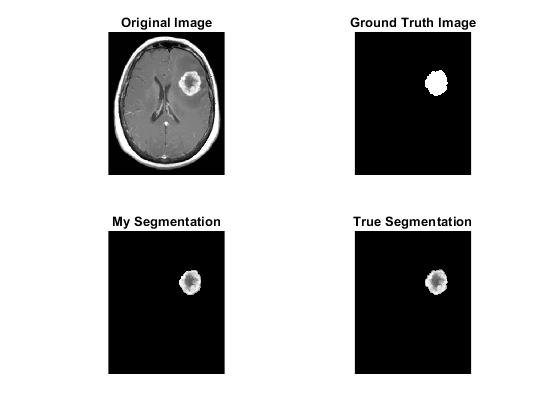


figure; subplot(2,2,1); imshow(brain,[]); title('Original Image');
subplot(2,2,2); imshow(truth); title('Ground Truth Image');
subplot(2,2,3); imshow(brain.*segmented,[]); title('My Segmentation');
subplot(2,2,4); imshow(brain.*truth,[]); title('True Segmentation');

### Custom Functions

#### *Region Growing*

function segmented = regionGrow(image,seedPoint,threshold)
    segmented = zeros(size(image)); % Initialize segmented matrix
    segmented(seedPoint(1),seedPoint(2)) = 1; % Starting seed point
    tried = zeros(size(image)); % Initialize already tried points matrix
    image = padarray(image,[1 1]); % Pad array with zeros so there are no edge issues
    while sum( tried(:) ~= segmented(:) )>0 % While there are still points to try ...
        [tryX,tryY] = find(segmented - tried); % Get all coordinates to try
        for i = 1:length(tryX)
            tried(tryX(i),tryY(i)) = 1; % Add test coordinates to 'tried' array
            value = image(tryX(i),tryY(i)); % Get value of current pixel
            
            % If pixel to the top left of the current pixel is within threshold
            if abs( image(tryX(i)-1,tryY(i)-1)-value ) < threshold
                % Then add this point to the segmented image
                segmented(tryX(i)-1,tryY(i)-1) = 1;
            end
            if abs( image(tryX(i)-1,tryY(i))-value ) < threshold %top pixel
                segmented(tryX(i)-1,tryY(i)) = 1;
            end
            if abs( image(tryX(i)-1,tryY(i)+1)-value ) < threshold %top right pixel
                segmented(tryX(i)-1,tryY(i)+1) = 1;
            end
            if abs(image(tryX(i),tryY(i)-1)-value ) < threshold %left pixel
                segmented(tryX(i),tryY(i)-1) = 1;
            end
            if abs( image(tryX(i),tryY(i)+1)-value ) < threshold %right pixel
                segmented(tryX(i),tryY(i)+1) = 1;
            end
            if abs( image(tryX(i)+1,tryY(i)-1)-value ) < threshold %bot left pixel
                segmented(tryX(i)+1,tryY(i)-1) = 1;
            end
            if abs( image(tryX(i)+1,tryY(i))-value ) < threshold %bottom pixel
                segmented(tryX(i)+1,tryY(i)) = 1;
            end
            if abs( image(tryX(i)+1,tryY(i)+1)-value ) < threshold %bot right pixel
                segmented(tryX(i)+1,tryY(i)+1) = 1;
            end
            
        end 
    end
end


#### *Dilation*

function dilated = dilation(image)
    dilated = image;
    for i=2:size(image,1)-1 % for all non-edge points
        for j=2:size(image,2)-1
            block = image(i-1:i+1,j-1:j+1); % find block within image
            if sum(block(:))>0 % if any point is active
                dilated(i-1:i+1,j-1:j+1) = 1; %make all points active
            end
        end
    end
end

#### *Erosion*

function eroded = erosion(image)
    eroded = image;
    for i=2:size(image,1)-1
        for j=2:size(image,2)-1
            block = image(i-1:i+1,j-1:j+1);
            if sum(block(:))<9
                eroded(i-1:i+1,j-1:j+1) = 0;
            end
        end
    end
end